% Define symbolic variable and differential equation
syms x(t)
a0 = 10.5; b0 = 6.5; k = 2.0;
dx_dt = k * (a0 - x) * (b0 - x);

% Solve the differential equation
solution = dsolve(diff(x, t) == dx_dt, x(0) == 0);
disp('The solution for x(t) is:');

The solution for x(t) is:


disp(solution);

$$\frac{13\,{\mathrm{e}}^{8\,t+\log\left(\frac{21}{13}\right)}-21}{2\,\left({\mathrm{e}}^{8\,t+\log\left(\frac{21}{13}\right)}-1\right)}$$

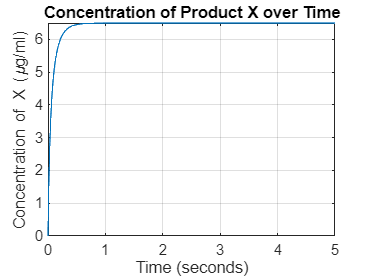


% Simplify and plot the solution
simplified_solution = simplify(solution);
figure('color', 'w');
fplot(simplified_solution, [0, 5]);
title('Concentration of Product X over Time');
xlabel('Time (seconds)');
ylabel('Concentration of X (\mug/ml)');
grid on;